# VISUALPCA

Visualize the principal compoenents from the heart disease data.

## Load data and perform PCA

load heartdisease
[pcs,scrs,~,~,pexp] = pca(numdata);

## Verify that components are uncorrelated

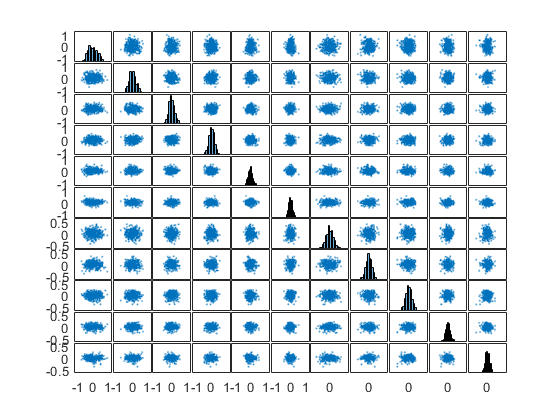

figure
plotmatrix(scrs)

## Visualize relationship between variables and components

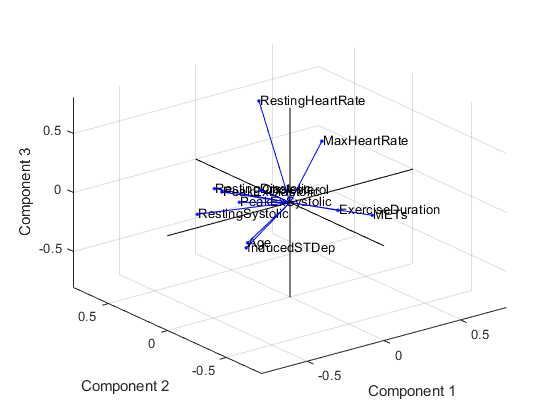

figure
biplot(pcs(:,1:3),'VarLabels',vars)

## Visualize components using a heatmap

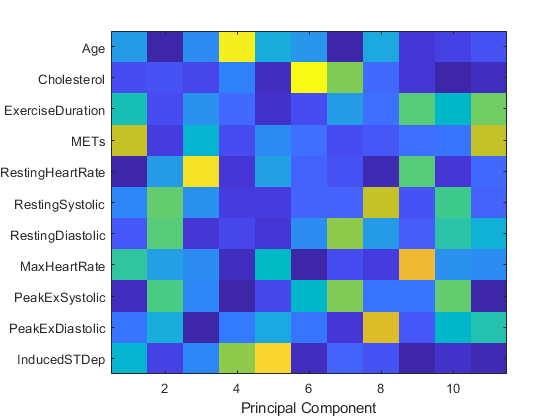

figure
imagesc(abs(pcs))
labelYTicks(vars)
xlabel('Principal Component')

## Visualize predictive power of components (predicting heart disease)

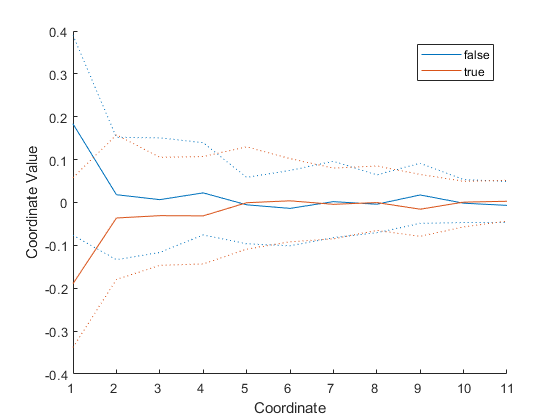

HD = heartdataNum.HeartDisease;
figure
parallelcoords(scrs,'Group',HD,'Quantile',0.25)

Equivalent approach

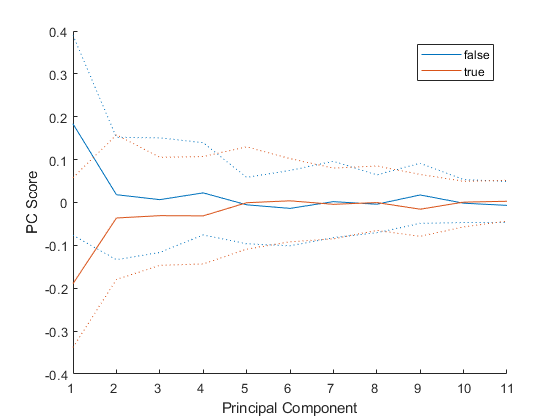

figure
parallelcoords(numdata,'Group',HD,'Quantile',0.25,'Standardize','PCA')